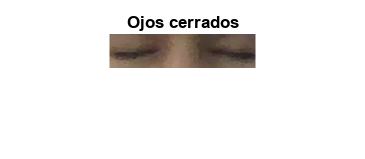

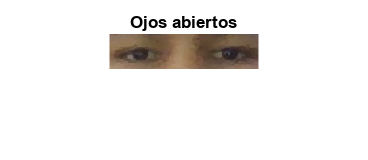

clear all;

n=1;

vid = videoinput('winvideo', 1, 'YUY2_1280x720');
src = getselectedsource(vid);
vid.ReturnedColorSpace = 'rgb';

start(vid)

for n=1:2;
    % Inicializando las variables que contendrán la suma 
    % de la imagen binarizada
    SUM1=0;
    SUM2=0;

    % Capturando una foto del video
    I = getsnapshot(vid);

    % Detección de los ojos mediante la detección de objetos en cascada 
    Detection= vision.CascadeObjectDetector('EyePairSmall');

    % Pasando a espacio de color de grises
    IEG = rgb2gray(I);
    region = step(Detection, IEG);
    r=region;
    t=size(r);


    if t(1,1)==true
        % Delimitando la imagen en los ojos
        Iface=imcrop(IEG,r);
        Rface=imcrop(I,r);

        figure
        bboxes = Detection(I);
        Ifaces = insertObjectAnnotation(I,"rectangle",bboxes,'Cara');
        
        % Uso de la aplicación "Color Thresholder"
        % Convirtiendo la imagen RGB al espacio de color HSV
        I = rgb2hsv(Rface);
        
        % Definir umbrales para el canal 1 en función de la configuración
        % del histograma del Matiz
        channel1Min = 0.118;
        channel1Max = 0.901;
        
        % Definir umbrales para el canal 1 en función de la configuración
        % del histograma de la Saturación
        channel2Min = 0.000;
        channel2Max = 0.238;
        
        % Definir umbrales para el canal 1 en función de la configuración
        % del histograma del Valor
        channel3Min = 0.107;
        channel3Max = 0.434;
        
        % Creando máscara basada en los umbrales de histograma elegidos
        sliderBW = (I(:,:,1) >= channel1Min ) & (I(:,:,1) <= channel1Max) & ...
            (I(:,:,2) >= channel2Min ) & (I(:,:,2) <= channel2Max) & ...
            (I(:,:,3) >= channel3Min ) & (I(:,:,3) <= channel3Max);
        BW = sliderBW;
        
        % Inicializando la imagen enmascarada de salida en función de 
        % la imagen de entrada.
        maskedRGBImage = Rface;
        
        % Estableciendi los píxeles de fondo donde BW es falso en cero.
        maskedRGBImage(repmat(~BW,[1 1 3])) = 0;
        
        % Suma de imagenes binarizadas
        if n == 1
            SUM1 = sum(BW,'all');
        else
            SUM2 = sum(BW,'all');
        end
        % Identificación de ojos abiertos o cerrados haciendo uso de la
        % suma anterior, teniendo en cuenta que la suma de los ojos
        % cerrados será cero con respecto a los abiertos
        if SUM1 > 1 || SUM2 > 1
            imshow(Rface)
            title("Ojos abiertos")
        else
            imshow(Rface)
            title("Ojos cerrados")
        end

    end

    n=n+1;
end


stop(vid)